clearvars;
clc;


# Import Video Tables

training_data_table = load('GP_50676_table.mat');
training_data_table = training_data_table.GP_50676_table;
height(training_data_table)

ans = 2231

Define the number of object classes to detect.

numClasses = width(training_data_table)-1;

## Augment Training Data

% rng(0);
% inputSize = [224 224 3];
% percent_to_automate = 5/100;
% number_of_imgs = floor((percent_to_automate*height(trainingDataTbl)))
% rand_images = randi([1 height(trainingDataTbl)], number_of_imgs, 1); % create 25 x 1 array to get 25 random images
% for i = 1:length(rand_images)
%     for j = 1:10
%         img_tbl = trainingDataTbl(rand_images(i),:); %read row
%         img = table2cell(img_tbl);
%         [save_image,img] = pre_aug_Image(img);
%         save_image_str = strcat('facility_aug_', int2str(i*j),'.png');
%         img_path = strcat(dir_str,'/',save_image_str);
%         imwrite(save_image, img_path, 'png');
%         % append to the table
%         img{1} = img_path;
%         img = cell2table(img, 'VariableNames',img_tbl.Properties.VariableNames);
%         trainingDataTbl = [trainingDataTbl;img];
%     end
% end

#### Show Examples:

% augmentedData = cell(9,1);
% img_tbl = trainingDataTbl(rand_images(2),:) %read row
% for k = 1:9
%     img = table2cell(img_tbl);
%     [save_image, img] = pre_aug_Image(img);
%     bb = [img{2};img{3};img{4};img{5}];
%     augmentedData{k} = insertShape(save_image,'Rectangle',bb);
% end
% figure
% montage(augmentedData,'BorderSize',9)

## Create Datastores for Data sets and Resize

imdsTrain = imageDatastore(training_data_table{:,'imageFilename'});
bldsTrain = boxLabelDatastore(training_data_table(:,2:5));
training_data = combine(imdsTrain, bldsTrain)

training_data =   CombinedDatastore with properties:

    UnderlyingDatastores: {[1×1 matlab.io.datastore.ImageDatastore]  [1×1 boxLabelDatastore]}


## Preprocess Images

inputSize = [416 416 3];
trainingDataForEstimation = transform(training_data,@(data)preprocessData(data,inputSize));

# **Anchor Boxes**

Sweep over all possible anchors to determine best fit uncomment to see the graph of performance

visualizeAnchorBoxes = true

visualizeAnchorBoxes = logical
   1


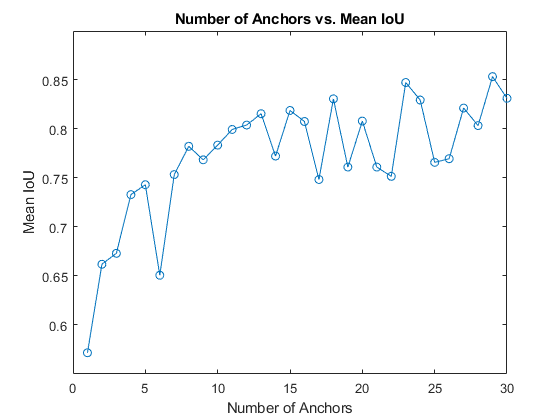

if visualizeAnchorBoxes
maxNumAnchors = 30;
meanIoU = zeros([maxNumAnchors,1]);
anchorBoxes = cell(maxNumAnchors, 1);
    for k = 1:maxNumAnchors
        % Estimate anchors and mean IoU.
        [anchorBoxes{k},meanIoU(k)] = estimateAnchorBoxes(trainingDataForEstimation,k);    
    end
    figure
    plot(1:maxNumAnchors,meanIoU,'-o')
    ylabel("Mean IoU")
    xlabel("Number of Anchors")
    title("Number of Anchors vs. Mean IoU")
end

## Visually Inspect, Determine A Good NumAnchors

numAnchors = 13

numAnchors = 13

**Changed from trainingData in the example to trainingDataForEstimation to put it in the correct format.**

[anchorBoxes, meanIoU] = estimateAnchorBoxes(trainingDataForEstimation, numAnchors)

anchorBoxes =    102   130
    51    98
   109    98
   219   122
   175   183
    76   189
   263   213
    78   116
   182   266
    84    78


meanIoU = 0.8101

For more information on choosing anchor boxes, see [Estimate Anchor Boxes from Training Data](docid:vision_ug#mw_671cb7a6-5a7a-4147-acf3-3e1fd7d3dfd7) (Computer Vision Toolbox™) and [Anchor Box Basics](docid:vision_ug#mw_f9f22f48-0ad0-4f37-8bc1-22a2046637f2).

# **Load in Network to begin Transfer Learning**

Load in tinyYolov2 without regression layer. 

% the exported network is saved as layers_1 in workspace (make function)
model = fullfile('Model.onnx');
net = importONNXNetwork('Model.onnx', "OutputLayerType", 'regression');
lgraph = yolov2Layers(inputSize,numClasses,anchorBoxes,net,'activation4');
network_string = "tinyYOLO_04"

network_string = "tinyYOLO_04"

## Train YOLO v2 Object Detector

Use `trainingOptions` to specify network training options. Set `'CheckpointPath'` to a temporary location. This enables the saving of partially trained detectors during the training process. If training is interrupted, such as by a power outage or system failure, you can resume training from the saved checkpoint.

learningRate = 1e-3;
epochSize = 100;
solverMethod = 'sgdm';
miniBatchsize = 16;
period = 10;
drop_factor = .8;
momentum = 0.975;
options = trainingOptions(solverMethod, ...
        'MiniBatchSize', miniBatchsize, ....
        'InitialLearnRate',learningRate, ...
        'MaxEpochs',epochSize,...
        'CheckpointPath', tempdir, ...
        'LearnRateSchedule', 'piecewise', ...
        'LearnRateDropPeriod', period, ...
        "LearnRateDropFactor", drop_factor, ...
        'Momentum', momentum, ...
        'Shuffle','never');
[detector,info] = trainYOLOv2ObjectDetector(trainingDataForEstimation,lgraph,options);

*************************************************************************
Training a YOLO v2 Object Detector for the following object classes:

* can
* glass
* other
* plastic

Training on single GPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     RMSE     |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:02 |        22.01 |        484.3 |          0.0010 |
|       1 |          50 |       00:00:52 |         2.06 |          4.2 |          0.0010 |
|       1 |         100 |       00:01:42 |         2.43 |          5.9 |          0.0010 |
|       2 |         150 |       00:02:32 |         2.41 |          5.8 |          0.0010 |
|       2 |         200 |       00:03:23 |         2.59 |          6.7 

**TEST DETECTOR **

Tests the detector on an image from the test dataset reserved earlier

val_data = load('facility_val_test_data.mat');
valDataTbl = val_data.ValTestData;
testDataset = true
if testDataset
    % test detector on    all the testing data to see if there is any detection
    detectedImages = 0;
    missedImages = 0;
    imageIndices = 1;
    for i = 1:length(valDataTbl.imageFilename) 
        I = imread(valDataTbl.imageFilename{i});
        I = imresize(I,inputSize(1:2));
        [bboxes,scores] = detect(detector,I);
        
        if(~isempty(bboxes))
            I = insertObjectAnnotation(I,'rectangle',bboxes,scores);
          
            detectedImagesIndexArray(imageIndices) = i;
            imageIndices = imageIndices + 1;
            
            detectedImages =  detectedImages + 1;
        else
            missedImages = missedImages + 1;
        end
    end
    detector_accuracy = detectedImages/height(valDataTbl) * 100;
    fprintf('total images: %d\n',length(valDataTbl.imageFilename));
    fprintf('detected images: %d\n',detectedImages);
    fprintf('missed images: %d\n',missedImages);
    fprintf('Accuracy Percentage, detected/missed: %f\n',detectedImages/length(valDataTbl.imageFilename) * 100);
end

## Display A Detected Image From The Detected Images Set

Usage: replace* detectedImagesIndexArray(3) *with *detectedImagesIndexArray( your desired number in the range of detectedImagesIndex range ) *

    if detectedImages > 0 
        figure
        img = imread(valDataTbl.imageFilename{detectedImagesIndexArray(4)});
        img = imresize(img,inputSize(1:2));
        [bboxes,scores] = detect(detector,img);
        if(~isempty(bboxes))
            img = insertObjectAnnotation(img,'rectangle',bboxes,scores); 
        end
        imshow(img)
    end



## Evaluate Detector Using Test Set

Evaluate the trained object detector on a large set of images to measure the performance. Computer Vision Toolbox™ provides object detector evaluation functions to measure common metrics such as average precision (`evaluateDetectionPrecision`) and log-average miss rates (`evaluateDetectionMissRate`). For this example, use the average precision metric to evaluate performance. The average precision provides a single number that incorporates the ability of the detector to make correct classifications (precision) and the ability of the detector to find all relevant objects (recall).

Run the detector on all the test images.

imdsVal = imageDatastore(valDataTbl{:,'imageFilename'});
bldsVal = boxLabelDatastore(valDataTbl(:,2:5)); 
val_data = combine(imdsVal, bldsVal);
preprocessedValData = transform(val_data,@(data)preprocessData(data,inputSize));
detectionResults = detect(detector, preprocessedValData);

Evaluate the object detector using average precision metric.

[ap,recall,precision] = evaluateDetectionPrecision(detectionResults, preprocessedValData);
save(network_string, 'detector', 'ap', 'recall', 'precision'); % save detector


## Supporting Functions

function B = augmentData(A)
% Apply random horizontal flipping, and random X/Y scaling. Boxes that get
% scaled outside the bounds are clipped if the overlap is above 0.25. Also,
% jitter image color.
B = cell(size(A));

I = A{1};
sz = size(I);
if numel(sz)==3 && sz(3) == 3
    I = jitterColorHSV(I,...
        'Contrast',0.3,...
        'Hue',0,...
        'Saturation',0.2,...
        'Brightness',0.2);
end

% Randomly flip and scale image.
% tform = randomAffine2d('XReflection',true,'Scale',[1 1.1]);
tform = randomAffine2d('XReflection',true, "YReflection", true);
rout = affineOutputView(sz,tform,'BoundsStyle','CenterOutput');
B{1} = imwarp(I,tform,'OutputView',rout);

% Apply same transform to boxes.
[B{2},indices] = bboxwarp(A{2},tform,rout,'OverlapThreshold',0.25);
B{3} = A{3}(indices);

% Return original data only when all boxes are removed by warping.
if isempty(indices)
    B = A;
end
end

function data = preprocessData(data,targetSize)
% Resize image and bounding boxes to the targetSize.
scale = targetSize(1:2)./size(data{1},[1 2]);
data{1} = imresize(data{1},targetSize(1:2));
data{2} = floor(data{2});
%data{2}(2) = 1;
data{2} = correctData(data{2});
data{2} = bboxresize(data{2},scale); 
end

%%
function [img_to_save, img] = pre_aug_Image(img)
    % Resize image and bounding boxes to the targetSize.
    width = size(img);
    width = width(2);
    I = imread(img{1}); % file path
    sz = size(I);
    if numel(sz)==3 && sz(3) == 3
        I = jitterColorHSV(I,...
            'Contrast',0.3,...
            'Hue',0,...
            'Saturation',0.2,...
            'Brightness',0.3);
    end
    
    % Randomly flip and scale image
    tform = randomAffine2d('XReflection',true,'Scale',[1 1.1], "YReflection", true);
    rout = affineOutputView(sz,tform,'BoundsStyle','CenterOutput');
    B = imwarp(I,tform,'OutputView',rout);
    
    % Apply same transform to boxes.
    
    for col = 2:width
        img{col} = floor(img{col});
        img{col} = correctData(img{col});
        img{col} = bboxwarp(img{col},tform,rout,'OverlapThreshold',0.25);
    end
    img_to_save = B;
end

%%%
function data = correctData(data)

D = size(data);
length = D(1) * D(2);
if min(data,[],'all') == 0 
   for i=1:length
       if data(i) == 0 
           data(i) = 1;
       end
   end
end

end

## References

[1] Redmon, Joseph, and Ali Farhadi. "YOLO9000: Better, Faster, Stronger." 2017 IEEE Conference on Computer Vision and Pattern Recognition (CVPR). IEEE, 2017.

*Copyright 2019 The MathWorks, Inc.*